# Machine Learning: Multivariable Linear Regression

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this demo

- `demo.mlx` - MATLAB Live Script that steps you through the demo

- food_truck_data.txt - Dataset for linear regression with one variable

- housing_data.txt - Dataset for linear regression with multiple variables

- `plotData.m` - Function to display the dataset

- `computeCostMulti.m` - Cost function for multiple variables

- `gradientDescentMulti.m` - Gradient descent for multiple variables

- `featureNormalize.m `- Function to normalize features

- `normalEqn.m` - Function to compute the normal equations

- more_lm.mlx - Matlab Live script that steps you through the use of native MAtlab tools for linear regression

#### Clear existing variables and confirm that your Current Folder is set correctly

clear

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file food_truck_data`.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. 

Data plot before applying a linear regression model:

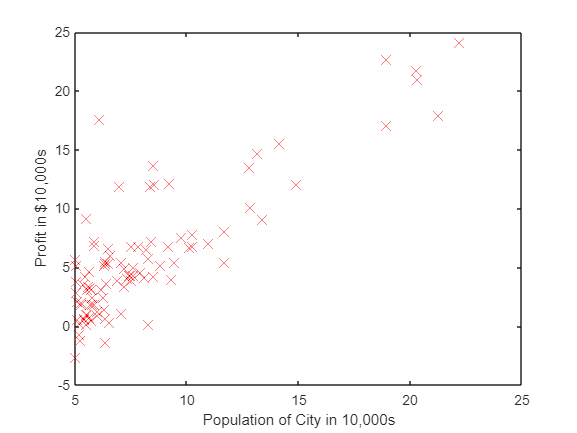

data = load('food_truck_data.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);


plot(X, y, 'rx', 'MarkerSize', 10); % Plot the data
ylabel('Profit in $10,000s'); % Set the y-axis label
xlabel('Population of City in 10,000s');

### 2.2 Gradient Descent

In this section, we fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data X to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01; % Learning rate

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

Calculating the cost function with the initial $\theta$ values [0 0].

% Compute and display initial cost with theta all zeros

ans = 32.0727

computeCost(X, y, theta)

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. 

The gradient descent updates the values of theta at each iteration and calculates the cost function. It keeps the history if the cost function in a vector.

Calculating theta using the gradient descent:

% Run gradient descent:
% Compute theta
[theta, ~] = gradientDescent(X, y, theta, alpha, iterations);

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.894597,
1.192915

Plotting the linear model and the training data:

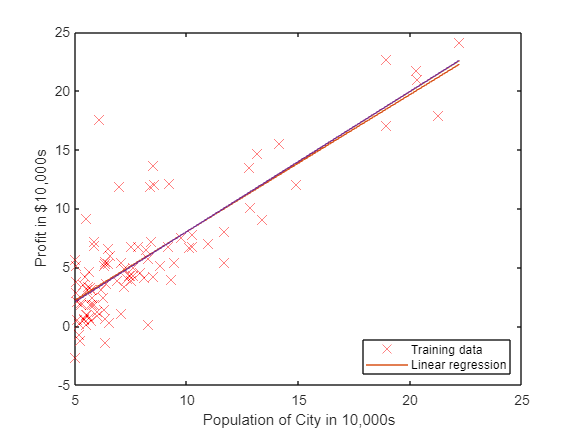

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression', 'Location','southeast')
hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 2806.045736


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 44558.060147


### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values.

 In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    Plotting `surface` and `contour:`

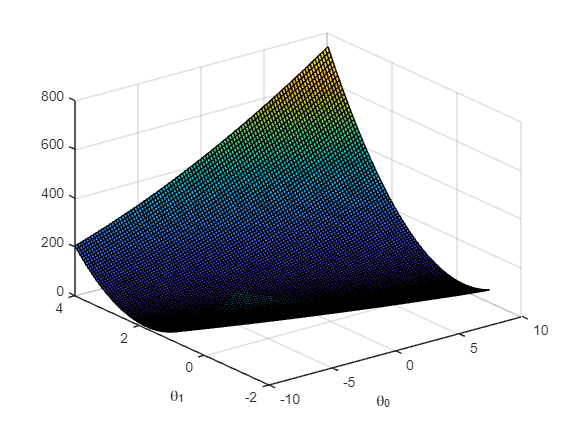

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');
% Contour plot
figure;

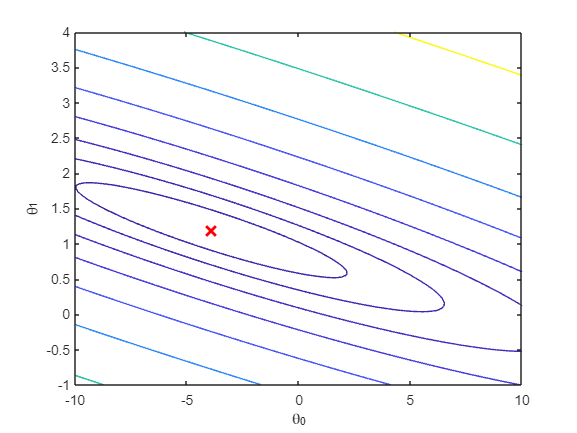

% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file housing_data`.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('housing_data.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

`We use the function in the file featureNormalize.m` to normalize training data. It's done for each feature as follows:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescent(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house

input_norm = ([1650 3] - mu) ./ sigma; % Feature Normalization

price = [1 input_norm] * theta; 

Theta computed from gradient descent:
340412.659574
110631.048958
-6649.472950

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Selecting learning rates**

It is desired to find a learning rate that makes the gradient descent algorithm converge quickly. 

You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call the `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

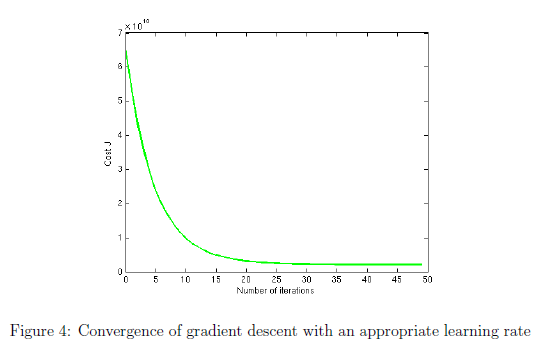

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

% Run gradient descent:

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.464622

% Choose some alpha value
alpha = 0.03;
num_iters = 75;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescent(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');
hold off

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

**Comparaison of learning rates:**

The following code runs the gradient descent algorithm with different values of the learning rate 'alpha'.

Then it plots the cost function $J(\theta)$ for each learning rate.

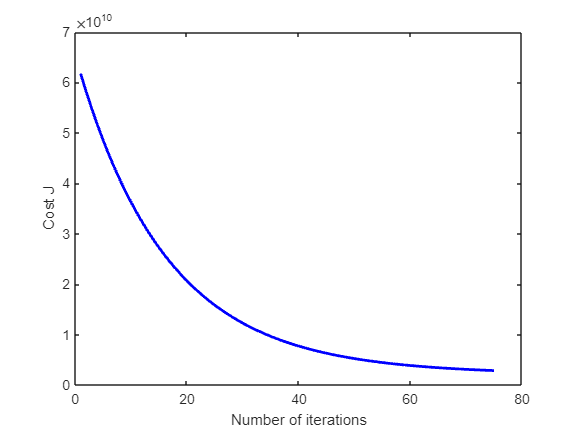

iterations = 50; % Number of iterations
alphas = [0.03 0.1 0.3 1]; % Possible values of the learning rate alpha
colors = ['-b', '-g', '-r', '-k'];

for i = 1:size(alphas, 2)

    theta = zeros(3, 1);
    alpha = alphas(i);
    [~, J_history] = gradientDescent(X, y, theta, alpha, iterations);
    plot(1:iterations, J_history, colors(i), 'DisplayName', sprintf('alpha = %.2f', alpha));
    
    hold on
    
end

xlabel('Number of iterations');
ylabel('Cost J');
legend('show', 'Location','northeast')
hold off

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

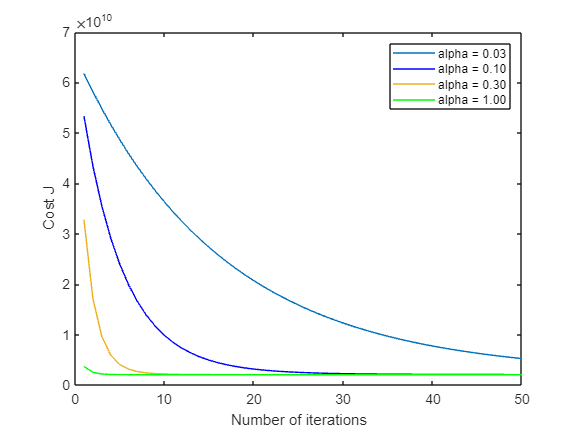

% Solve with normal equations:
% Load Data
data = readmatrix('housing_data.txt');
X = data(:, 1:2);
y = data(:, 3);

m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Calculating price estimate with Normal Equation: **

Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2).

Notice that we don't need any feature scaling.

% Estimate the price of a 1650 sq-ft, 3 br house. 

price = [1 1650 3] * theta; 

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);    

Theta computed from the normal equations:
89597.909544
139.210674
-8738.019113

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $293081.464335